
% figure R v.s. I %

clear all;
close all;

%load('E:\Data\2024-11-23\Rmax_vs_I.mat');
load('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\RvsI\RvsI.mat');


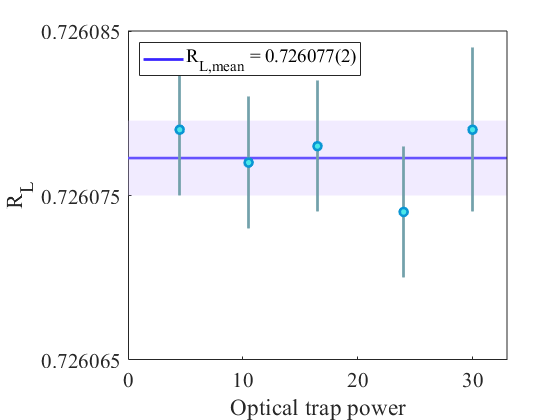


x = x*30;

err_mean1 = sqrt(sum(w1.* ((y1-y_mean1).^2+err1.^2) )./sum(w1));
err_mean1 = err_mean1/sqrt(length(x)-1);

x_low = 0*30;
x_high = 1.1*30;
y_low = 0.726065;
y_high = 0.726085;

f1 = figure; hold on;

plot([x_low x_high],[y_mean1 y_mean1],Color=[0.22 0.14 1],LineWidth=2);
n1 = [1 2 3 4];
patch_list = [x_low y_mean1-err_mean1;x_high y_mean1-err_mean1;x_high y_mean1+err_mean1;x_low y_mean1+err_mean1];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');

E1 = errorbar(x,y1,err1,'o', LineWidth=2, MarkerSize=6);

E1.CapSize = 0;
E1.MarkerEdgeColor = [0.04,0.59,0.83];
E1.MarkerFaceColor = [0.29,0.91,0.91];
E1.Color = [0.45,0.63,0.67];

set(gca,'FontSize',16,'FontName','Times New Roman','FontWeight','normal',...
    'YScale','linear','XScale','linear','Box','on');

xlim([x_low x_high]);
ylim([y_low,y_high]);
yticks([0.726065 0.726075 0.726085]);

grid off;
box off;

plot([x_low x_high],[y_high y_high],'Color',[0.15 0.15 0.15]);
plot([x_high x_high],[y_low y_high],'Color',[0.15 0.15 0.15]);

xlabel('Optical trap power');
ylabel('R_L');

legend(['R_{L,mean} = ',num2str(roundn(y_mean1,-6),'%.6f'),'(',num2str(round(err_mean1*1e6)),')'],'','', ...
    'Location','northwest','FontSize',14);

hold off;

set(f1,'Visible','on');


% savefig(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsI.fig');
% saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsI.png');
% saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsI.eps','psc');

% 
% save('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsI.mat');